Vdrive = 300

syms K tau s
V_s = Vdrive/s * (K/tau)/(s + 1/tau)

V_t = ilaplace(V_s)

for i = 1:3
    if i == 1
            data = readtable('output_free_wheel.txt');
            disp('output_free_wheel.txt')
    elseif i == 2
            data = readtable('output_floor_2s.txt');
            disp('output_floor_2s.txt')
    else
        data = readtable('output_floor_3s.txt');
        disp('output_floor_3s.txt')
    end
L_vel = data.Var1;
R_vel = data.Var2;
R_vel = erase(R_vel,';');
R_vel = cellfun(@str2num,R_vel);
t = 0:0.02:10;
t = t(1:length(L_vel))';
V_mean = (L_vel + R_vel)/2;


% figure(i)
% plot(t, L_vel)
% hold on
% plot(t, R_vel)
% plot(t, V_mean)
% legend('left', 'right', 'mean', 'location', 'best')

V_time_domain = @(K, tau, t) Vdrive*K*(1-exp(-t/tau));

figure;

meanFit = createStepResponseFit(t, V_mean)
% figure;
% rightFit = createStepResponseFit(t, R_vel)
% leftFit = createStepResponseFit(t, L_vel)
end

taus = [];
Ks = [];

Freewheel

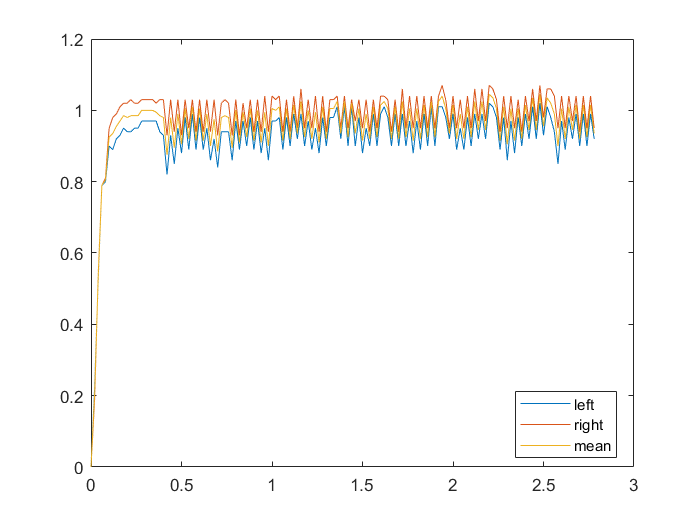

meanFit =      General model:
     meanFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003242  (0.003215, 0.003269)
       tau =     0.04489  (0.03906, 0.05073)

data = readtable('output_free_wheel.txt');

L_vel = data.Var1;
R_vel = data.Var2;
R_vel = erase(R_vel,';');
R_vel = cellfun(@str2num,R_vel);
t = 0:0.02:10;
t = t(1:length(L_vel))';
V_mean = (L_vel + R_vel)/2;


figure()
plot(t, L_vel)
hold on
plot(t, R_vel)
plot(t, V_mean)
legend('left', 'right', 'mean', 'location', 'best')

V_time_domain = @(K, tau, t) Vdrive*K*(1-exp(-t/tau));

meanFit = createStepResponseFit(t, V_mean)

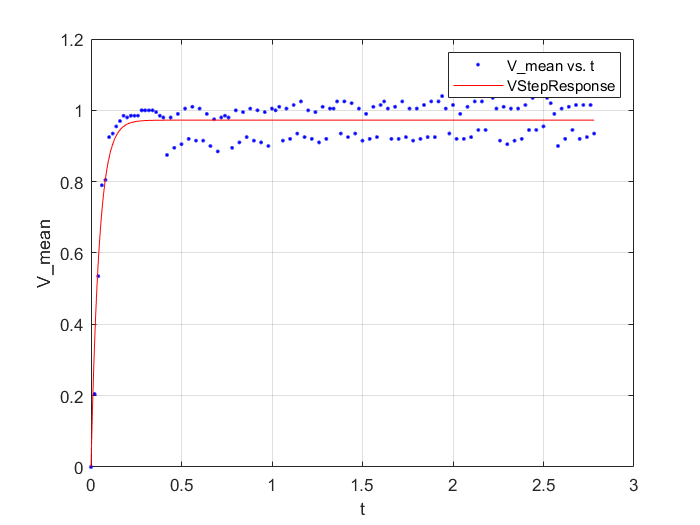

rightFit =      General model:
     rightFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003341  (0.003313, 0.003368)
       tau =     0.04616  (0.04032, 0.052)

taus = [taus; meanFit.tau];
Ks = [Ks; meanFit.K];

rightFit = createStepResponseFit(t, R_vel)

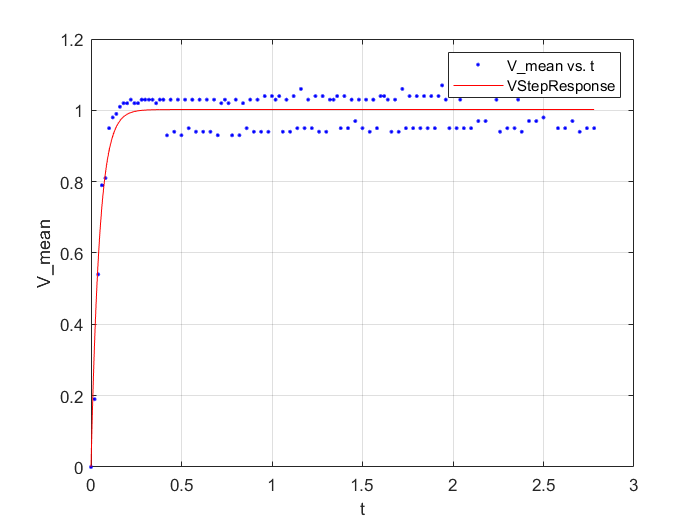

leftFit =      General model:
     leftFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003142  (0.003115, 0.00317)
       tau =      0.0435  (0.03743, 0.04956)

leftFit = createStepResponseFit(t, L_vel)

Output Floor 3s

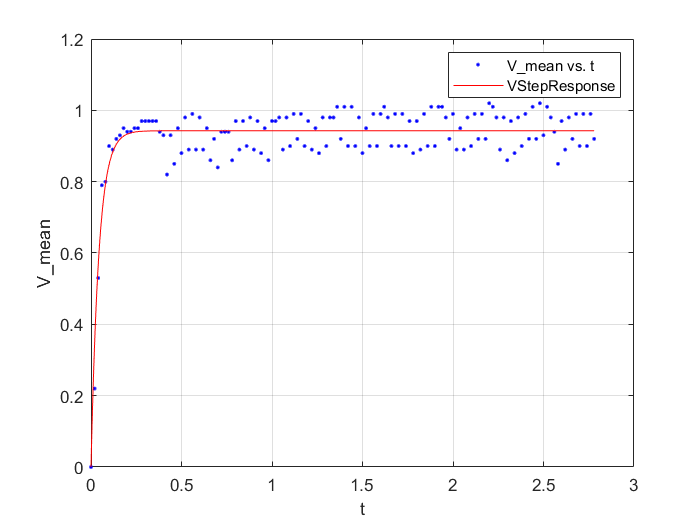

meanFit =      General model:
     meanFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003308  (0.003277, 0.003339)
       tau =     0.06508  (0.05714, 0.07303)

data = readtable('output_floor_3s.txt');

L_vel = data.Var1;
R_vel = data.Var2;
R_vel = erase(R_vel,';');
R_vel = cellfun(@str2num,R_vel);
t = 0:0.02:10;
t = t(1:length(L_vel))';
V_mean = (L_vel + R_vel)/2;


figure()
plot(t, L_vel)
hold on
plot(t, R_vel)
plot(t, V_mean)
legend('left', 'right', 'mean', 'location', 'best')

V_time_domain = @(K, tau, t) Vdrive*K*(1-exp(-t/tau));

meanFit = createStepResponseFit(t, V_mean)

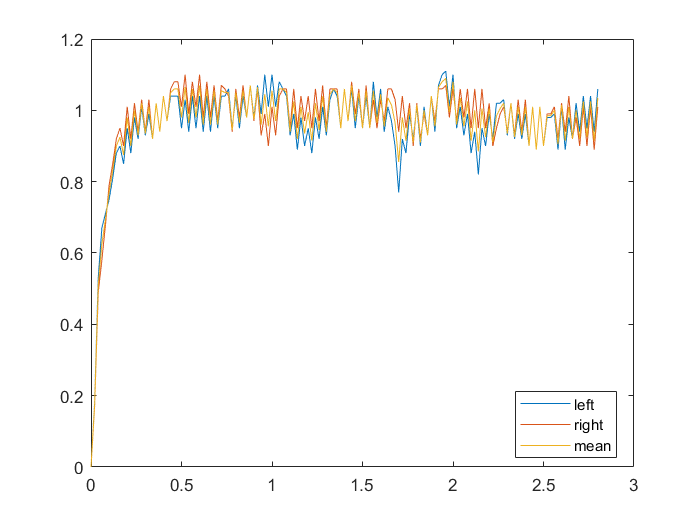

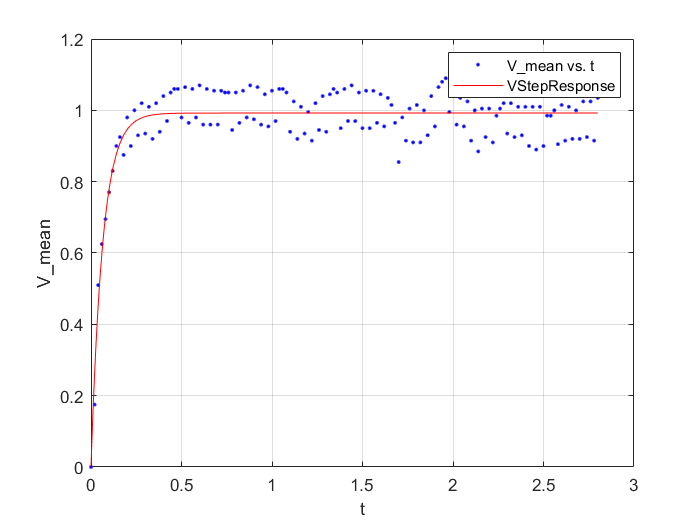

rightFit =      General model:
     rightFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003338  (0.003306, 0.00337)
       tau =      0.0661  (0.05798, 0.07423)

taus = [taus; meanFit.tau];
Ks = [Ks; meanFit.K];
rightFit = createStepResponseFit(t, R_vel)

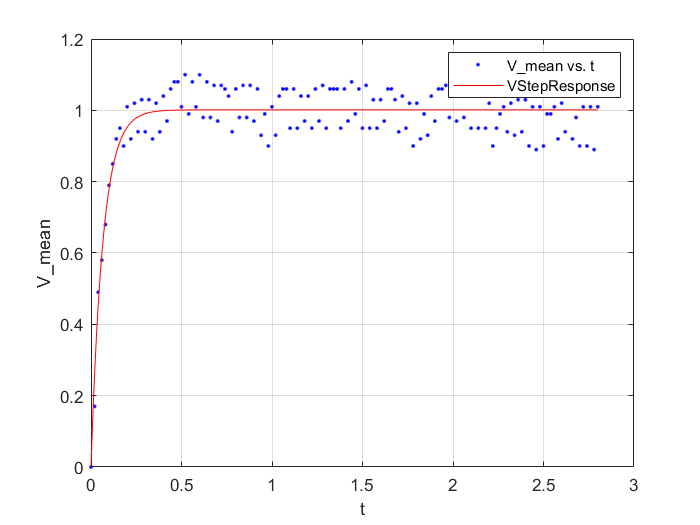

leftFit =      General model:
     leftFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003278  (0.003242, 0.003314)
       tau =     0.06394  (0.05481, 0.07307)

leftFit = createStepResponseFit(t, L_vel)

Output Floor 2s

data = readtable('output_floor_2s.txt');

L_vel = data.Var1

L_vel =          0
    0.1800
    0.5800
    0.6400
    0.7500
    0.7200
    0.8100
    0.7900
    0.8900
    0.8400


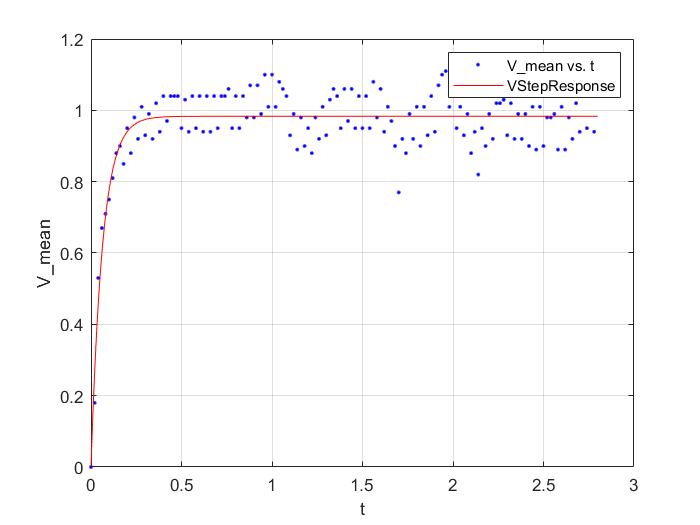

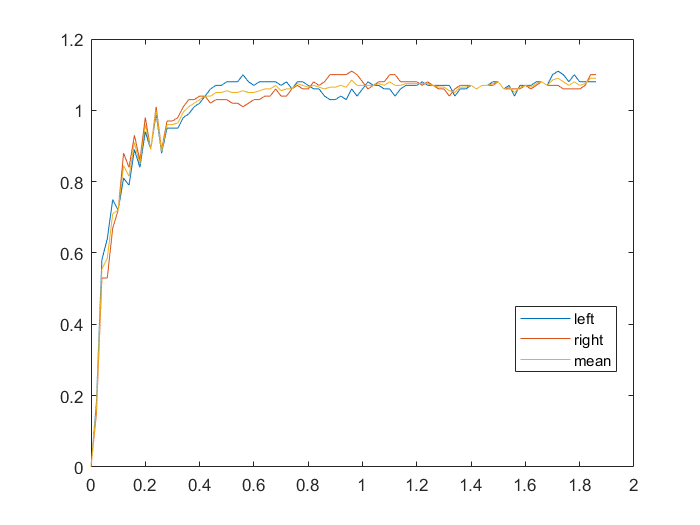

meanFit =      General model:
     meanFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003537  (0.003513, 0.003562)
       tau =     0.08621  (0.08083, 0.09159)

R_vel = data.Var2;
R_vel = erase(R_vel,';');
R_vel = cellfun(@str2num,R_vel);
L_vel = L_vel(1:94);
R_vel = R_vel(1:94);
t = 0:0.02:10;
t = t(1:length(L_vel))';
V_mean = (L_vel + R_vel)/2;


figure()
plot(t, L_vel)
hold on
plot(t, R_vel)
plot(t, V_mean)
legend('left', 'right', 'mean', 'location', 'best')

V_time_domain = @(K, tau, t) Vdrive*K*(1-exp(-t/tau));

meanFit = createStepResponseFit(t, V_mean)

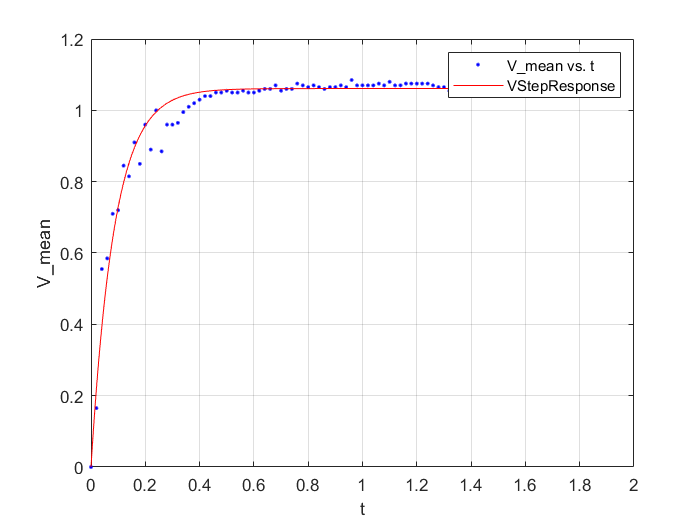

rightFit =      General model:
     rightFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003537  (0.003511, 0.003562)
       tau =     0.08662  (0.08098, 0.09225)

taus = [taus; meanFit.tau];
Ks = [Ks; meanFit.K];

rightFit = createStepResponseFit(t, R_vel)

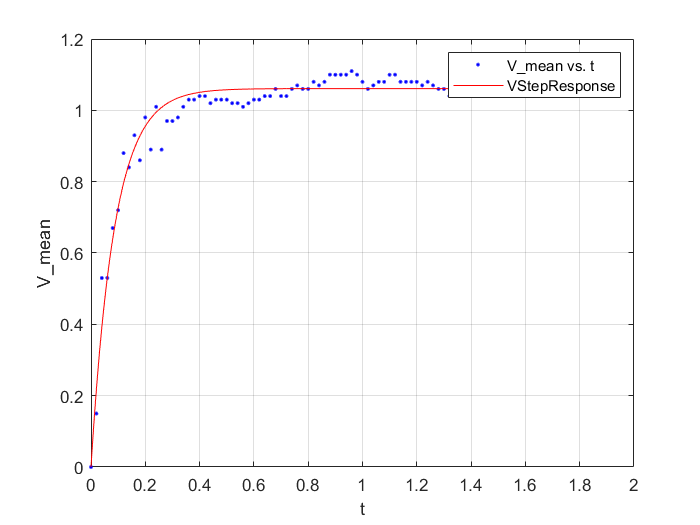

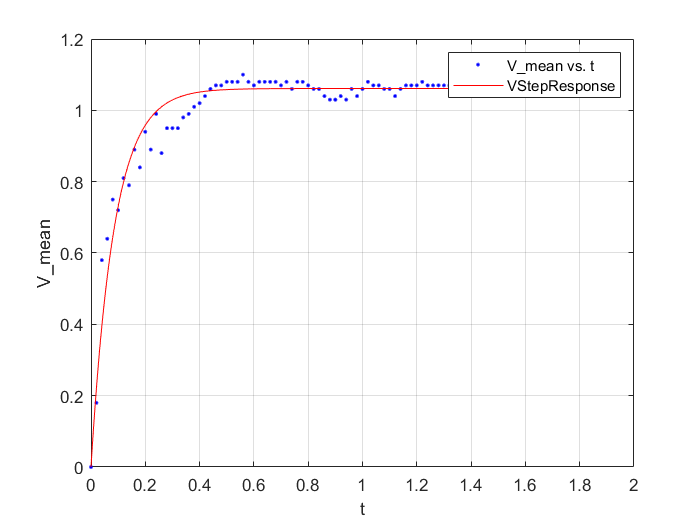

leftFit =      General model:
     leftFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003537  (0.003507, 0.003568)
       tau =     0.08574  (0.07914, 0.09235)

leftFit = createStepResponseFit(t, L_vel)

Ks

Ks =     0.0032
    0.0033
    0.0035


K = mean(Ks)

K = 0.0034

taus

taus =     0.0449
    0.0651
    0.0862


tau = mean(taus)

tau = 0.0654


save('MotorResponse3-2-23', 'tau', 'K', 'taus', 'Ks')